options = bodeoptions;
options.FreqUnits = 'Hz';
load('new_plant_trav_gyro.mat')

figure;
gain = 0.9;
trav_gyro_gain = gain;

bode(gain*simulation_trav_gyro_plant,options)
title('Gain added Bode')
hold on
bode(gain*sys_mes_trav_gyro,options)
grid on
xlim([1,200])

## PRINT

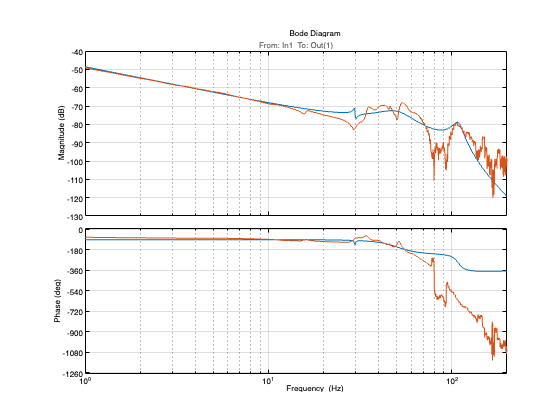

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/trav_gyro_plant_sim_mes.png')

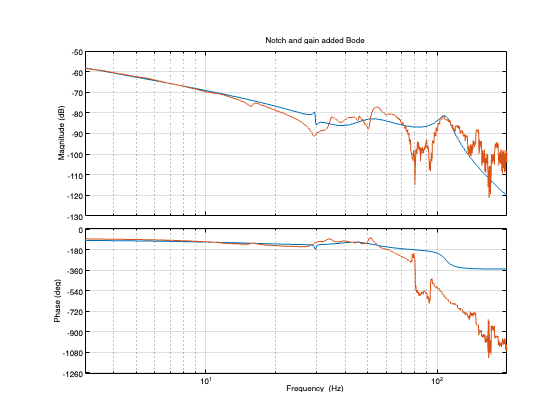

figure;
load('new_trav_gyro_notch.mat')
trav_gyro_notch = tf(new_trav_gyro_notch);


bode(gain*simulation_trav_gyro_plant*trav_gyro_notch,options);
hold on;
bode(gain*sys_mes_trav_gyro*trav_gyro_notch,options)
title('Notch and gain added Bode')
grid on
hold off
xlim([3,200])

sys_trav_gyro = simulation_trav_gyro_plant*trav_gyro_gain *trav_gyro_notch;
opts = pidtuneOptions('PhaseMargin',40);
[C_pi_trav_gyro_simple,info] = pidtune(sys_trav_gyro,'PI',21.7,opts)

C_pi_trav_gyro_simple =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 690, Ki = 1.37e+04
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 21.7000
           PhaseMargin: 40.0000



Kp_trav_gyro =C_pi_trav_gyro_simple.Kp+1830;
Ki_trav_gyro =C_pi_trav_gyro_simple.Ki/0.9;

PI_trav_gyro = tf(1/s*Ki_trav_gyro+Kp_trav_gyro );



sys_control = PI_trav_gyro*sys_trav_gyro;

figure;
margin(sys_control)
grid on
xlim([1,200])

## PRINT

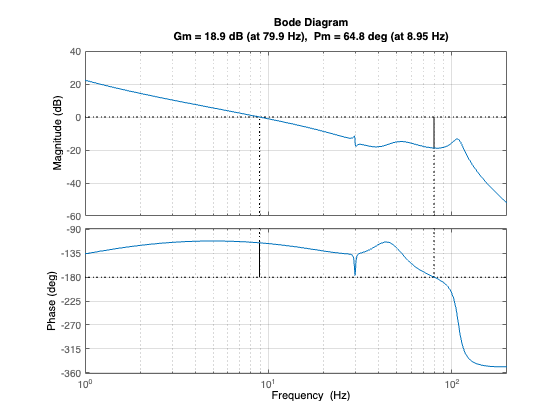

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/trav_gyro_sim_controlled.png')

figure;
margin(PI_trav_gyro*sys_mes_trav_gyro*trav_gyro_notch)
grid on
xlim([1,200])

## PRINT

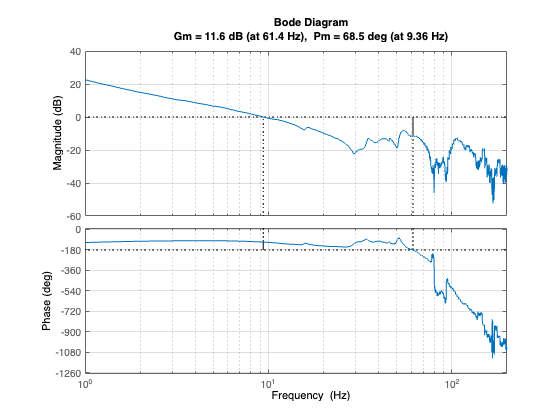

saveas(gcf,'/Users/ohadformanair/Documents/project_plots/trav_gyro_mes_controlled.png')

PC_trav_gyro2 = sys_control;
